# Solution to *Atlantic Hurricanes* exercise

## 1. Load MAT-file

Load the data in `hurricaneData.mat`. This file contains two variables: `Dates` (as a `datetime` variable) and `Windspeed` (in miles per hour). The data represents observations of Atlantic storms. Observations are made every 6 hours of storms where the wind speed is at least 39 mph (the official definition of a “tropical storm”).

load hurricaneData

## 2. Plot the wind speeds through time

Create a plot of the wind speeds through time, marked with points.

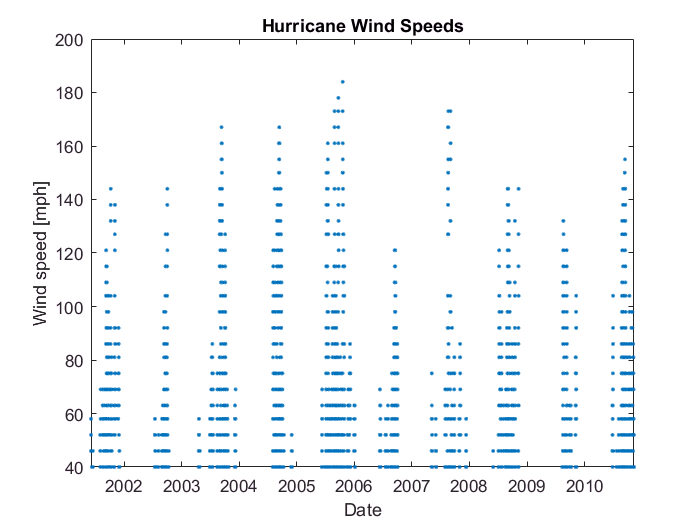

plot(Dates,Windspeed,'.')
xlabel('Date')
ylabel('Wind speed [mph]')
title('Hurricane Wind Speeds')

## 3. Find when the 10 highest wind speeds were recorded

Sort the data by wind speed (descending) using the `sort` function. Find when the top 10 wind speeds were recorded. 

**Hint** The sort function can return the original index as an optional output.

[byWS,byWSidx] = sort(Windspeed,'descend');
windiest = Dates(byWSidx(1:10))

windiest =    19-Oct-2005 12:00:00
   22-Sep-2005 06:00:00
   28-Aug-2005 18:00:00
   22-Sep-2005 00:00:00
   19-Oct-2005 06:00:00
   21-Aug-2007 06:00:00
   03-Sep-2007 00:00:00
   03-Sep-2007 06:00:00
   11-Sep-2003 18:00:00
   11-Sep-2004 18:00:00

## 4. Determine month for each hurricane

Use an appropriate function to create a vector representing the month (as a number 1 – 12) for each observation.

mth = month(Dates);

## 5. Make a histogram of the number of observations by month

Use this vector to make a histogram of the number of observations in each month using the histogram function. Use the months (1 – 12) as the bins for the histogram by using an optional input to `histogram` to set the `BinMethod` property to `integers`

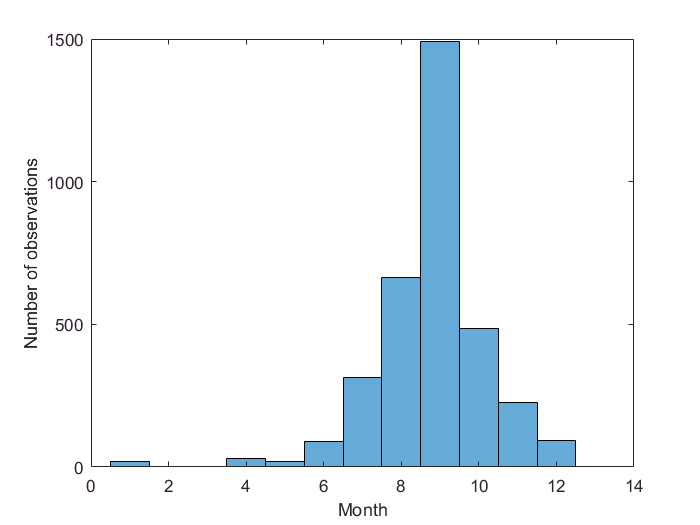

histogram(mth,'BinMethod','integers')
xlabel('Month')
ylabel('Number of observations')